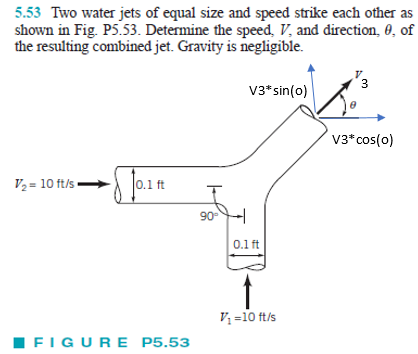

# given

u = symunit;
rho = 1.94*u.slug/u.ft^3;

# inflow properties

% ----------------
D1 = 0.1*u.ft;
A1 = sympi*D1^2/4;
V1 = 10*u.ft/u.s;
V1x = 0;
V1y = V1;
mdot1 = rho*A1*V1;
% ----------------
D2 = 0.1*u.ft;
A2 = sympi*D2^2/4;
V2 = 10*u.ft/u.s;
V2x = V2;
V2y = 0;
mdot2 = rho*A2*V2;
% ----------------

# outflow properties

syms A3 V3 theta positive;
V3x(V3, theta) = V3*cos(theta);
V3y(V3, theta) = V3*sin(theta);
mdot3(A3, V3) = rho*A3*V3;

# conservation of mass

eqn = sym.zeros(3,1);
eqn(1) = mdot1+mdot2 == mdot3;

# conservation of linear momentum (x-direction)

eqn(2) = 0 == -mdot1*(V1x)-mdot2*(V2x)+formula(mdot3)*formula(V3x);

# conservation of linear momentum (y-direction)

eqn(3) = 0 == -mdot1*(V1y)-mdot2*(V2y)+formula(mdot3)*formula(V3y);

# solution

[A3 V3 theta] = solve(eqn, [A3 V3 theta]); %#ok
A3 = simplify(A3);
V3 = simplify(V3);
V3_vpa = vpa(V3, 3) %#ok

$$V3\_vpa = 7.07\,\frac{\mathrm{ft}}{s}$$

theta = rewrite(theta*u.rad, u.deg)

$$theta = 45\,\deg$$

clear V3_vpa;
clearassum;